# Power-Split Hybrid Electric Vehicle Model with Direct Input

## Start Engine while Driving with MG2

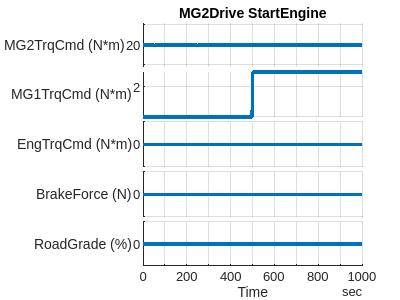

mdl = "PowerSplitHEV_system_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

PowerSplitHEV_params

set_param(mdl+"/Controller & Environment", "ReferencedSubsystem", ...
  "PowerSplitHEV_DirectInput_refsub");

builder = PowerSplitHEV_DirectInput_InputSignalBuilder;
builder.Plot_tf = true;

hevDirectInputData = MG2Drive_StartEngine(builder, ...
  "RoadGrade_Const_pct", 0 , ...
  ...
  "MG2TorqueCommand_1_Nm", 20, ...
  "MG2TorqueCommand_2_Nm", 20, ...
  "MG2TorqueCommand_3_Nm", 20, ...
  "MG2TrqCmdChange_1_StartTime", seconds(1), ...
  "MG2TrqCmdChange_1_EndTime", seconds(2), ...
  "MG2TrqCmdChange_2_StartTime", seconds(3), ...
  "MG2TrqCmdChange_2_EndTime", seconds(4), ...
  ...
  "MG1TorqueCommand_1_Nm", 0, ...
  "MG1TorqueCommand_2_Nm", 3, ...
  "MG1TorqueCommand_3_Nm", 3, ...
  "MG1TrqCmdChange_1_StartTime", seconds(500), ...
  "MG1TrqCmdChange_1_EndTime", seconds(502), ...
  "MG1TrqCmdChange_2_StartTime", seconds(504), ...
  "MG1TrqCmdChange_2_EndTime", seconds(505), ...
  ...
  "EngineTorqueCommand_1_Nm", 0, ...
  "EngineTorqueCommand_2_Nm", 0, ...
  "EngineTorqueCommand_3_Nm", 0, ...
  "EngTrqCmdChange_1_StartTime", seconds(502), ...
  "EngTrqCmdChange_1_EndTime", seconds(502 + 2), ...
  "EngTrqCmdChange_2_StartTime", seconds(800), ...
  "EngTrqCmdChange_2_EndTime", seconds(802), ...
  ...
  "StopTime", seconds(1000) );

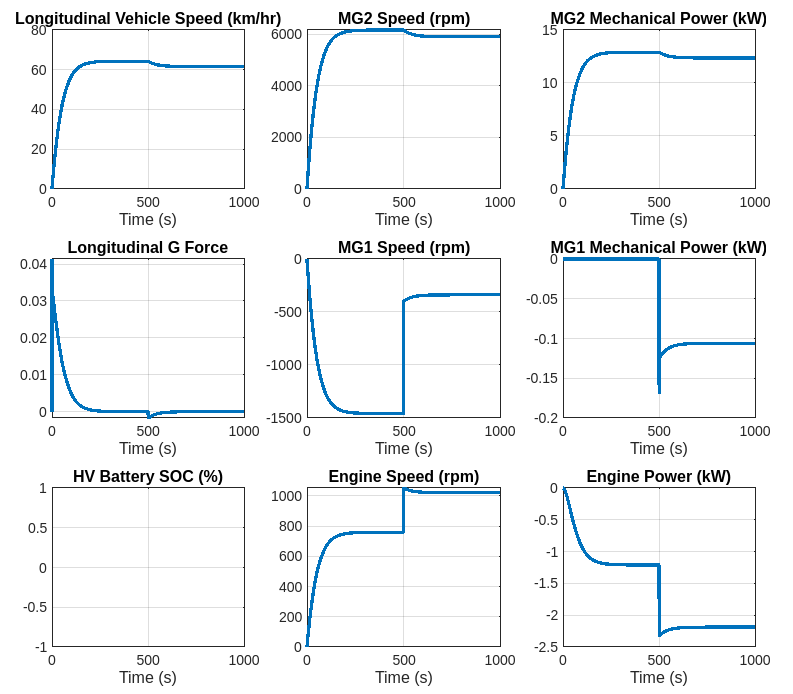


% Load data in the base workspace.
% This allows the Run button to work.
hevDirect_InputSignals = hevDirectInputData.Signals;
hevDirect_InputBus = hevDirectInputData.Bus;
t_end = hevDirectInputData.Options.StopTime_s;

simIn = Simulink.SimulationInput(mdl);
simIn = setModelParameter(simIn, "StopTime", num2str(t_end));
simIn = setVariable(simIn, "hevDirect_InputSignals", hevDirect_InputSignals);
simIn = setVariable(simIn, "hevDirect_InputBus", hevDirect_InputBus);

simOut = sim(simIn);

fig = figure;
PowerSplitHEV_plot_result_compact( "Dataset",simOut.logsout, "PlotParent",fig );

*Copyright 2021-2022 The MathWorks, Inc.*